clear all,close all,clc
addpath('../../../../../MATLAB')
% addpath('../../../../../MATLAB/FeaturesExtraction');
% m = DelsysM()
d1 = load('Snooze.txt');
d2 = load('Rock.txt');
d3 = load('Paper.txt');
d4 = load('Scissor.txt');
d = [d1, d2, d3, d4];
size(d)

ans =            2       96120


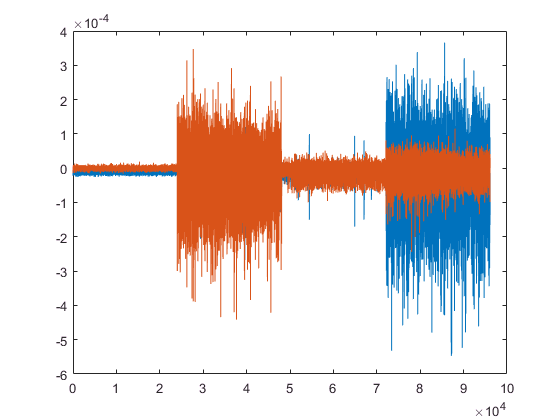

figure();plot(d(2,:));
hold on;plot(d(1, :));

动作次序分别为：Snooze, Rock, Paper, Scissor

所以，由此建议，为了能够更好地区分Snooze与Paper，要

1. 做动作上有意的有所区别；

2. 找到更好的电极粘贴位置

fE.featuresCell = {'MAV'};
fE.LW = 128;
fE.LI = 64;

addpath('../../../../../MATLAB/FeaturesExtraction');
sampleX1 = Rawdata2SampleMatrix(d1, fE);
sampleX2 = Rawdata2SampleMatrix(d2, fE);
sampleX3 = Rawdata2SampleMatrix(d3, fE);
sampleX4 = Rawdata2SampleMatrix(d4, fE);
size(sampleX1)

ans =    374     2


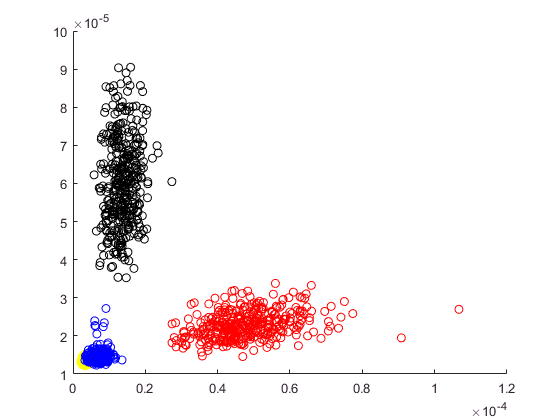

figure;
% - Snooze
scatter(sampleX1(:, 1), sampleX1(:,2), 'y');hold on;
% - Rock
scatter(sampleX2(:, 1), sampleX2(:,2), 'r');hold on;
% - Paper
scatter(sampleX3(:, 1), sampleX3(:,2), 'b');hold on;
% - Scissor
scatter(sampleX4(:, 1), sampleX4(:,2), 'k');hold on;

Summary:

由此可见，针对Paper与Scissors的区分，还需要找其他的不同点：

1. 肌肉的粘贴位置不同，在信号源上找不同；

2. 提取不同的特征，探索更多的特征；

结论：

经检验，并没有发现更好的特征能够明显区分其中混合的两者

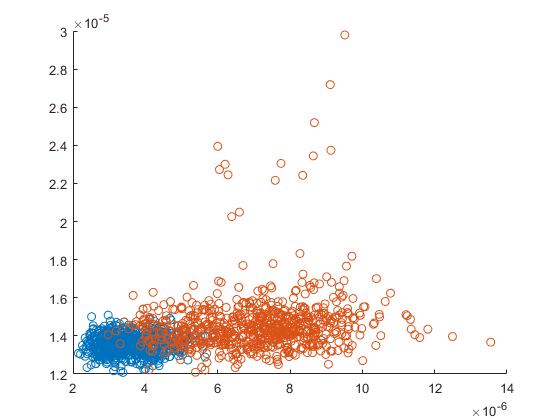

fE.featuresCell = {'MAV'};
fE.LW = 128;
fE.LI = 32;
sampleX1 = Rawdata2SampleMatrix(d1, fE);
sampleX3 = Rawdata2SampleMatrix(d3, fE);

figure;
% - Paper
scatter(sampleX1(:, 1), sampleX1(:,2));hold on;
% - Scissor
scatter(sampleX3(:, 1), sampleX3(:,2));hold on;

利用LDA的投影-最大化（类间离散度/类内离散度）对原特征空间中的分类问题**锦上添花**-哪怕不进行降维，也是一种**锦上添花**变换

fE.featuresCell = {'MAV'};
fE.LW = 128;
fE.LI = 64;
X1 = Rawdata2SampleMatrix(d1, fE);
X2 = Rawdata2SampleMatrix(d2, fE);
X3 = Rawdata2SampleMatrix(d3, fE);
X4 = Rawdata2SampleMatrix(d4, fE);

addpath('../../../../../MATLAB/DimensionReduction')
tic
clf = LDA(1);
clf.SimpleTrainM({X1, X2, X3, X4});
% clf.trainM({X1, X2, X3, X4});
clf.GetAccuracy({X1, X2, X3, X4})

ans =     0.9893         0    0.0107         0
         0    0.9973    0.0027         0
    0.1578         0    0.8422         0
         0         0    0.0053    0.9947


toc

LDA model comparasion

1. `ans = 降维，2->2`

`    0.9920         0    0.0080         0`

`         0    0.9973    0.0027         0`

`    0.1604         0    0.8396         0`

`         0         0    0.0053    0.9947`

`2. ans = 降维， 2->1`

`    0.9786         0    0.0214         0`

`         0    0.9920    0.0080         0`

`    0.2193         0    0.7807         0`

`    0.1230         0         0    0.8770`

`3. ans = 不降维`

`    0.9893         0    0.0107         0`

`         0    0.9973    0.0027         0`

`    0.1578         0    0.8422         0`

`         0         0    0.0053    0.9947`

clf = LDA(1);
% clf.SimpleTrainM({X2, X3, X4});
clf.trainM({X2, X3, X4});

LDA reduction is being conducted.


clf.GetAccuracy({X2, X3, X4})

ans =     0.9840    0.0160         0
         0    1.0000         0
         0    0.0374    0.9626


`ans = 不降维`

`    0.9973    0.0027         0`

`         0    1.0000         0`

`         0    0.0053    0.9947`

Summary:

两个改进方向：

1. 将休息动作单独扔出去用阈值估计，判别分类；

2. 增加最终结果输出的滑动窗，以时间为代价提高最终结果的分辨率

    并且，也没有必要如此高速的输出识别结果